## Cold plate parameterization 

In this we will carry out a trade-study to investigate different cold plate designs and compare a layout with serpentine U-channles (Figure 1) with a layout with parallel channels (Figure 2). This script is used to vary geometric parameters and compare performance of the two designs in terms of heat transfer and pressure drop. 

The following schematic shows the relevant input parameters that will be used:

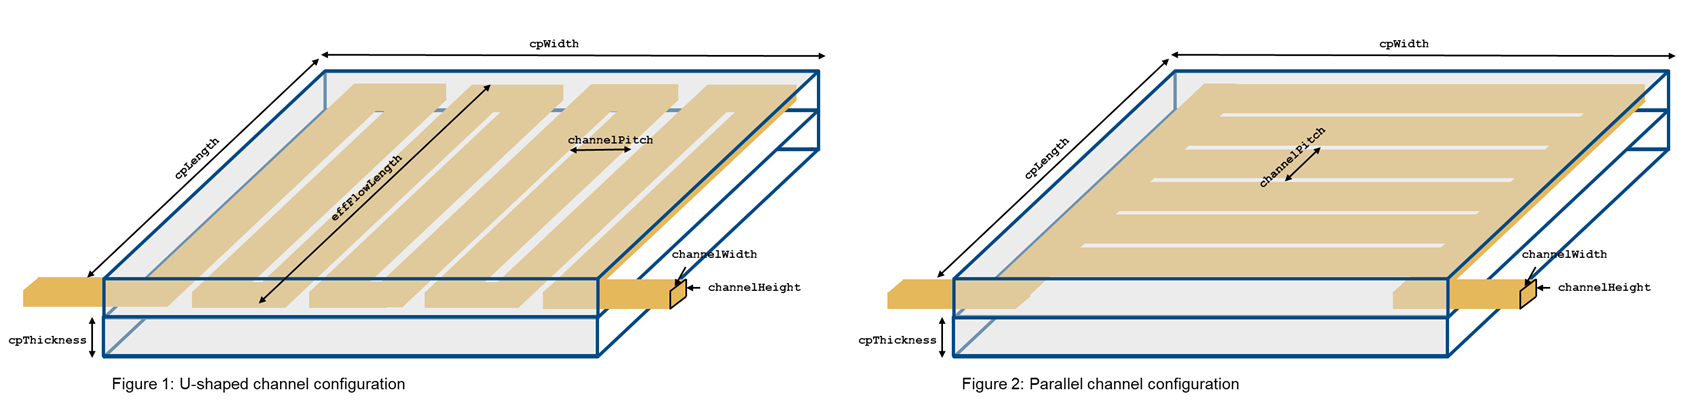

#### Geometric and material parameters of cold plate and cold plate channels:

The U-shaped configuration and the parallel channels configuration will perform differently in terms heat dissipation and pressure drop depending on size of plate and channel geometry. We will perform a parametric sweep across geometric parameter variations and evaluate performance for both configurations by looking at the final device temperature which has to stay below a certain values and the pressure drop across the cold plate. 

For simplicity, we will vary the cold plates length and width, which will largely influence the overall channel length and surface area for convection available. Specifically for the U-shaped confuguration the overall length will contribute significantly to the pressure drop. For different channel areas we will only vary the channel width and leave the channel height at a constant value. 

cpLength            = simscape.Value(160:20:340, 'mm');     % (mm)
cpWidth             = simscape.Value(160:20:340, 'mm');     % (mm)
cpThickness         = simscape.Value(5, 'mm');              % (mm)

channelWidth        = simscape.Value( 1:1:4, 'mm');         % (mm)
channelHeight       = simscape.Value( 8, 'mm');             % (mm)
channelMargin       = simscape.Value( 10, 'mm');            % mm
channelPitch        = channelWidth + simscape.Value(3, 'mm');


#### Additional parameters and cold plate material parameters

% deviceD              = simscape.Value(75, 'mm');            % Device thickness
% cpK                  = simscape.Value(167, 'W/(m*K)');      % Cold plate thermal conductivity
% channelRoughness     = simscape.Value(15e-6, 'm');          % Channel roughness
% cpDeviceSurfaceArea  = pi*(deviceD/2)^2;                    % Device surface area

### Set up parameter sweep for cold plate configuration

To compare the two configurations both are setup in one model:

open_system("example_compareColdPlates")

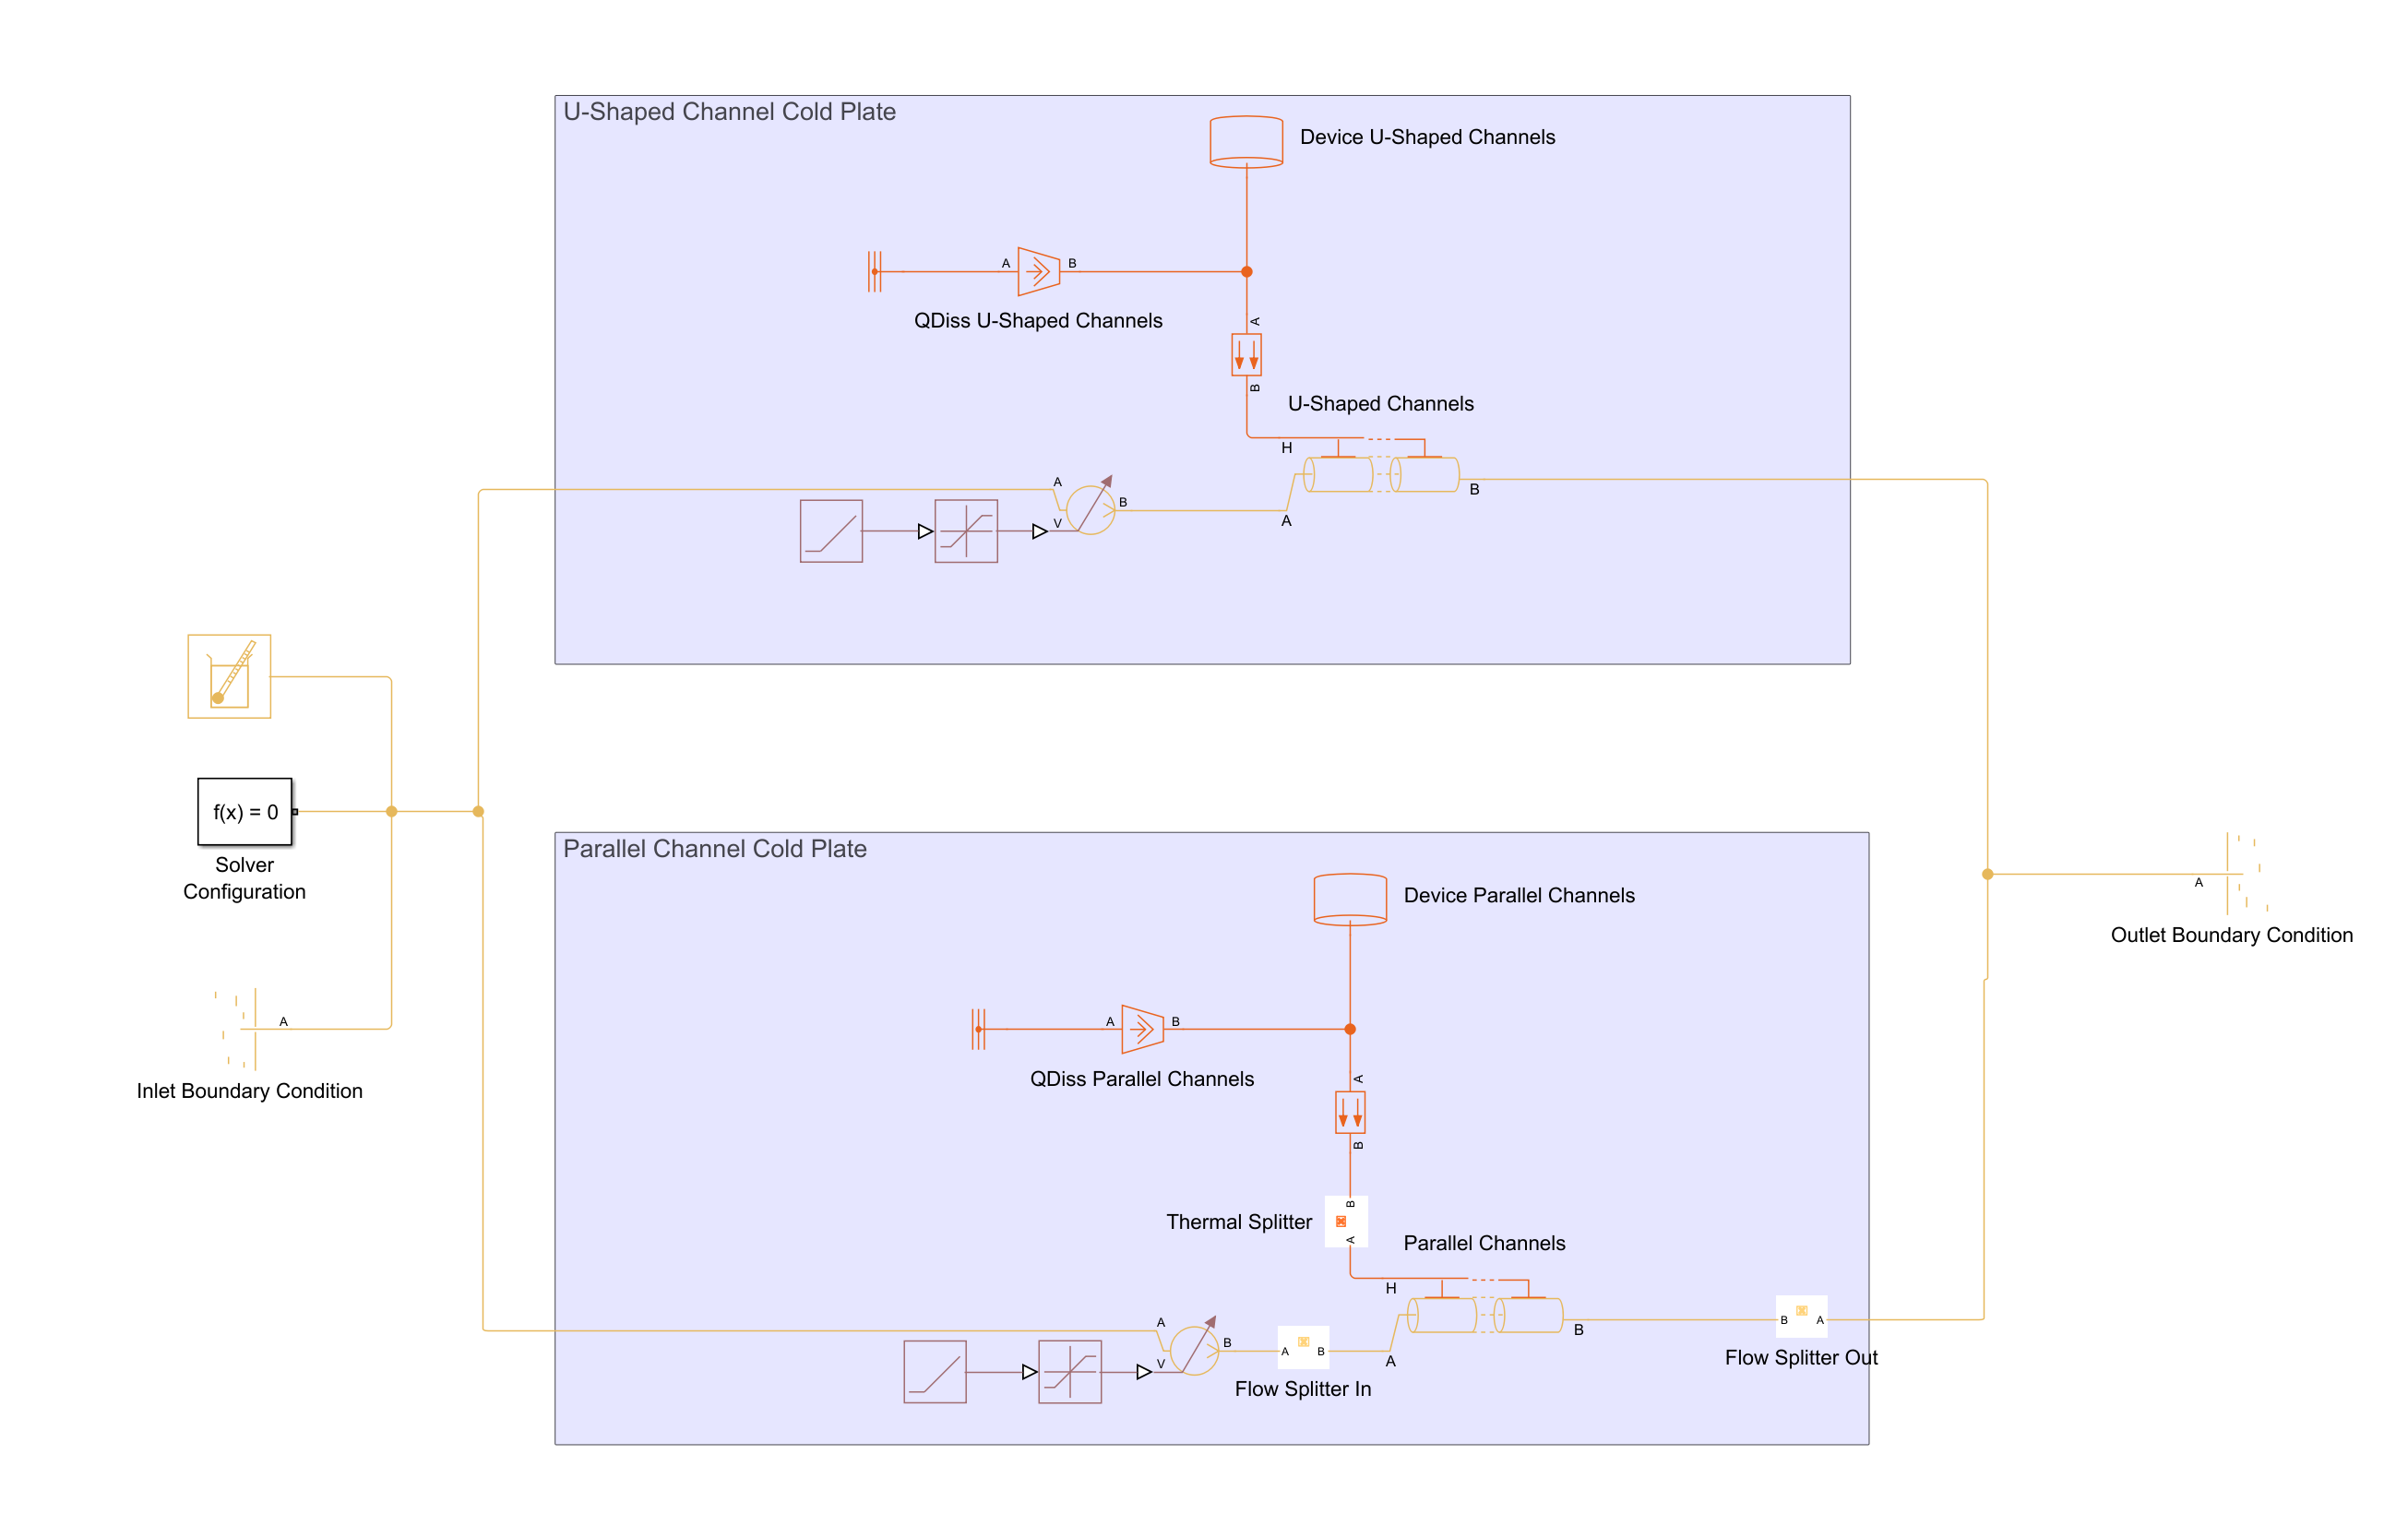

For both confugurations Pipe (TL) blocks are used to represent the geometry. Note that for the parallal channel configurations a "Flow Splitter" component is added on both sides of the pipe, and a "Thermal Splitter" is added at the Pipe (TL) thermal node. Assuming the parallel channels have an equal geometry and the manifold is designed in such a way, that the flow is evenly split between flow channels, we can only model one channel, for such a case the Flow Splitter acts as a multiplier and divider to make sure in the thermal liquid domain the flow is divided at cold plate input and multiplied at output. Similarly the Thermal Splitter will divide the heat flow rate into the pipe. The multiplying and dividing factor will be the number of parallel channels. Both splitters are provided as a custom library:

open("C:\Git\TMTutorial\Libraries\supplemental_lib.slx")

For the parameteric sweep a [Simulink.SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput.html) object is used. In this model the Model Workspace is already populated with parameters needed by the model, that have been defined in the [ColdPlate](matlab:open('.\ColdPlate.mlx')), this avoids having to transfer base workspace variables to parallel workers when using parallel simulations in the next step. 

mdlName = "example_compareColdPlates";
clear simInp

% Pre-allocate SimulationInput
simInp(numel(cpLength),numel(cpWidth), numel(channelWidth)) = Simulink.SimulationInput(mdlName);

for i = 1:numel(cpLength)
    for j = 1:numel(cpWidth)
        for k = 1:numel(channelWidth)

            channelPitch = channelWidth(k) + simscape.Value(3, 'mm');
            % U-shaped channels
            effFlowLengthU        = cpLength(i) - 2*channelMargin;                                    % Effective flow length of channels for U-shaped configuration
            numPassesU            = floor((cpWidth(j) - 2*channelMargin)/(2*channelPitch));           % Number of channel "U" passes based on the channel pitch for U-shaped configuration
            channelLengthU        = numPassesU*2*effFlowLengthU;                                      % Derived total channel length for U-shaped configuration

            % Parallel channels
            channelLengthP        = cpWidth(j) - 2*channelMargin;                                     % Flow length of each parallal channel for parallel configuration
            numChannelsP          = floor((cpLength(i) - 2*channelMargin)/channelPitch);

            % Shared parameters
            channelArea           = channelHeight*channelWidth(k);                                       % Channel cross-sectional area
            channelDh             = 2*channelWidth(k)*channelHeight/(channelHeight+channelWidth(k));  % Channel hydraulic diameter

            % Calculating additional equivalent length to determine pressure drop
            % U-shaped channels
            numBendU              = numPassesU*4;                                                     % Number of 90 degree bends in U-shaped configuration
            equivalentLengthU     = numBendU*60*channelDh;                                            % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
            % Parallel channels
            numBendP              = 2;                                                                % Number of 90 degree bends in parallel channel configuration
            equivalentLengthP     = numBendP*60*channelDh;                                            % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
            

            % Populating the Simulation.Input with variables, additionaly a
            % PostSimFcn is set to calculate device temperature and cold
            % plate pressure drop for every run (see function at bottom of
            % this script
            simInp(i,j,k)         = Simulink.SimulationInput(mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelWidth", channelWidth(k).value('mm'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channnelLengthU", channelLengthU.value('m'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channnelLengthP", channelLengthP.value('m'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("equivalentLengthU", equivalentLengthU.value('m'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("equivalentLengthP", equivalentLengthP.value('m'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("numChannelsP", numChannelsP, "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setVariable("channelArea", channelArea.value('mm^2'), "Workspace",mdlName);
            simInp(i,j,k)         = simInp(i,j,k).setPostSimFcn(@(simOut)postSimFcn(simOut));
        end
    end
end


#### Run and visualize

 Parsim allows to speed up the simulation by 

simOut = parsim(simInp, UseFastRestart="on", ShowSimulationManager ="on" );

[27-Nov-2025 16:55:08] Checking for availability of parallel pool...
[27-Nov-2025 16:55:08] Starting Simulink on parallel workers...
[27-Nov-2025 16:55:08] Configuring simulation cache folder on parallel workers...
[27-Nov-2025 16:55:08] Loading model on parallel workers...
[27-Nov-2025 16:55:10] Running simulations...


[27-Nov-2025 16:56:58] Cleaning up parallel workers...



TDeviceU = zeros(size(simInp));
TDeviceP = zeros(size(simInp));
dpColdPlateU = zeros(size(simInp));
dpColdPlateP = zeros(size(simInp));

for i = 1:numel(cpLength)
    for j = 1:numel(cpWidth)simOut
        for k = 1:numel(channelWidth)
            TDeviceTemp = simOut(i,j,k).simlog.Device_U_Shaped_Channels.T.series.values('degC');
            TDeviceU(i,j,k) = TDeviceTemp(end);
            TDeviceTemp = simOut(i,j,k).simlog.Device_Parallel_Channels.T.series.values('degC');
            TDeviceP(i,j,k) = TDeviceTemp(end);

            pATemp = simOut(i,j,k).simlog.U_Shaped_Channels.A.p.series.values('bar');
            pBTemp = simOut(i,j,k).simlog.U_Shaped_Channels.B.p.series.values('bar');
            dpColdPlateU(i,j,k) = pATemp(end)-pBTemp(end);

            pATemp = simOut(i,j,k).simlog.Parallel_Channels.A.p.series.values('bar');
            pBTemp = simOut(i,j,k).simlog.Parallel_Channels.B.p.series.values('bar');
            dpColdPlateP(i,j,k) = pATemp(end)-pBTemp(end);
        end
    end
end

Unrecognized field name "simlog".


figure


tiledlayout(2,2)
nexttile
colormap hot
clim([25 80])

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value('m'),cpWidth.value('m'),TDeviceU(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title('U-Shaped Channels: Device Temperature')
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("T [°C]")
hold off


nexttile
colormap hot
clim([25 80])

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value('m'),cpWidth.value('m'),TDeviceP(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title('Parallel Channels: Device Temperature')
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("T [°C]")
hold off

nexttile
colormap parula

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value('m'),cpWidth.value('m'),dpColdPlateU(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title('U-Shaped Channels: Pressure Drop')
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("\DeltaP [bar]")

hold off

nexttile
colormap parula

hold on
for k = 1:numel(channelWidth)
    surf(cpLength.value('m'),cpWidth.value('m'),dpColdPlateP(:,:,k), LineStyle = "none", FaceAlpha = 1/k)
    view([32 32])
    colorbar
end
title('Parallel Channels: Pressure Drop')
xlabel("Channel length [m]")
ylabel("Channel width [m]")
zlabel("\DeltaP [bar]")

hold off



#### Calculate derivative parameters

This sections calculates derived geometric parameters from the above selected values. Additionally to account for additional pressure losses for the bends in both configurations, we will use an approach using the equivalent length factor that can be accounted for in the pipe components. This was chosen, since the Simscape pipe blocks allow for additional fittings to be accounted for using the equivalent length method. 

% % U-shaped channels
% effFlowLengthU        = cpLength - 2*channelMargin;                                 % Effective flow length of channels for U-shaped configuration
% numPassesU            = floor((cpWidth - 2*channelMargin)/(2*channelPitch));        % Number of channel "U" passes based on the channel pitch for U-shaped configuration
% channelLengthU        = numPassesU*2*effFlowLengthU;                                % Derived total channel length for U-shaped configuration
% channelHTCSurfaceAreaU= channelLengthU*2*(channelWidth+channelHeight);               % Channel surface area for convective heat transfer for U-shaped configuration
%
% % Parallel channels
% channelLengthP        = cpWidth - 2*channelMargin;                                  % Flow length of each parallal channel for parallel configuration
% numChannelsP          = floor((cpLength - 2*channelMargin)/channelPitch);
% channelHTCSurfaceAreaP= channelLengthP*2*(channelWidth+channelHeight)*numChannelsP; % Channel surface area for convective heat transfer for U-shaped configuration
%
% % Shared parameters
% channelArea           = channelHeight*channelWidth;                                 % Channel cross-sectional area
% channelDh             = 2*channelWidth*channelHeight/(channelHeight+channelWidth);  % Channel hydraulic diameter
% cpDeviceSurfaceArea   = pi*(deviceD/2)^2;                                           % Device surface area
%
% % Calculating additional equivalent length to determine pressure drop
% % U-shaped channels
% numBendU              = numPassesU*4;                                               % Number of 90 degree bends in U-shaped configuration
% equivalentLengthU     = numBendU*60*channelDh;                                      % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow
% % Parallel channels
% numBendP              = 2;                                                          % Number of 90 degree bends in parallel channel configuration
% equivalentLengthP     = numBendP*60*channelDh;                                      % Using an equivalent length to hydraulic diamater ratio of 60 for a 90° mitered elbow

#### Calculate performance

The convective heat transfer coefficient in the cold channels can be determined using the Gnielinksi correlation. This is the same approach that is being used inside the Pipe (TL) component. For simplicity, we are using the fluid properties at an assumed inlet temperature of 25°C. The Reynolds number laminar flow upper limit and the Reynolds number turbultent flow lower limit is assumed to be at 2000 and 4000 respectively. This is then used to determine the thermal resistance of the convective heat transfer path. 

% htcU = calculateHTCPipe(channelDh,channelArea, mDot, 2000, 4000, kCoolant,channelRoughness/channelDh,muCoolant,PrCoolant);
% htcP = calculateHTCPipe(channelDh,channelArea, mDot/numChannelsP, 2000, 4000, kCoolant,channelRoughness/channelDh,muCoolant,PrCoolant);
% RconvU  = 1/(htcU*channelHTCSurfaceAreaU);
% RconvP  =  1/(htcP*channelHTCSurfaceAreaP);

The thermal resistance due to conduction is then determined using the cold plate specifications and its material properties

% Rcond  = cpThickness/(cpK*cpDeviceSurfaceArea);

The two combines give the total resistance

% RtotalU = RconvU+Rcond;
% disp(RtotalU.value('deltaK/W'))
% RtotalP = RconvP+Rcond;
% disp(RtotalP.value('deltaK/W'))

function [simOut] = postSimFcn(simOut)
    TDeviceTemp = simOut.simlog.Device_U_Shaped_Channels.T.series.values('degC');
    simOut.TDeviceU = TDeviceTemp(end);
    TDeviceTemp = simOut.simlog.Device_Parallel_Channels.T.series.values('degC');
    simOut.TDeviceP = TDeviceTemp(end);
    
    pATemp = simOut.simlog.U_Shaped_Channels.A.p.series.values('bar');
    pBTemp = simOut.simlog.U_Shaped_Channels.B.p.series.values('bar');
    simOut.dpColdPlateU = pATemp(end)-pBTemp(end);
    
    pATemp = simOut.simlog.Parallel_Channels.A.p.series.values('bar');
    pBTemp = simOut.simlog.Parallel_Channels.B.p.series.values('bar');
    simOut.dpColdPlateP = pATemp(end)-pBTemp(end);

end